# ACM 11: Week 6 Exercise 2 - Newton-Cotes integration

**(0) Names of all group members: Kyle McGraw**

## Newton-Cotes Rules

In this exercise we will explore the convergence of the simple trapezoid and simple Simpson's rules for numerical integration of the function:


$$f(x)=\frac{1}{\sqrt{2\pi}}\exp(-x^2/2) + \exp(3x)$$


The code block below sets up the function to be integrated, bounds for integration, number of quadrature points, and the exact value for comparison.

% function to be integrated
f = @(x) 1/sqrt(2*pi)*exp(-x.^2/2) + exp(3*x);

% bounds
a = -1.5; b = 1.5; 

% quadrature spaces
N = 50;

% exact integral for comparison
exact =  integral(f,a,b)

exact = 30.8684

The rectangle rule estimates this integral as follows: 


$$\int_a^b f(x)\,\text{d}x \approx \sum_{i=1}^N f(x_i) \Delta x$$


 The code block below implements the rectangle rule.

rectangle = 0;
x = linspace(a,b,N+1);
dx = x(2) - x(1);
for i=1:N
    rectangle = rectangle + dx*f(x(i));
end
rectangle

rectangle = 28.2491

The trapezoid rule is given by

$\int_a^b f(x) \,\text{d}x \approx \sum_{i=1}^N \frac12 (f(x_i) + f(x_{i+1}))\Delta x$.

**(1) In the code block below, implement the trapezoid rule.**

trapezoid = 0;
x = linspace(a,b,N+1);
dx = x(2) - x(1);
for i=1:N
    trapezoid = trapezoid + dx*1/2*(f(x(i))+f(x(i+1)));
end
trapezoid

trapezoid = 30.9492

Simpson's rule is given by


$$\int_a^b f(x)\,\text{d}x \approx \sum_{i=1}^{N/2} \frac {f(x_{2i-1}) + 4f(x_{2i}) + f(x_{2i+1}) }3 \Delta x$$


**(2) In the code block below, implement Simpson's rule.**

simpson = 0;
x = linspace(a,b,N+1);
dx = x(2) - x(1);
for i=1:N/2
    simpson = simpson + dx*(f(x(2*i-1))+4*f(x(2*i))+f(x(2*i+1)))/3;
end
simpson

simpson = 30.8686

**(3) Now let's observe the error rates for both methods using different values of N. Compute the trapezoid and Simpson's approximations along with their absolute errors compared to the exact value. **

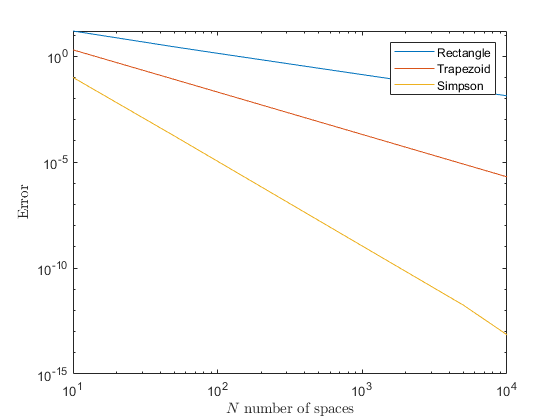

% Convergence study
N_vals = [10 50 100 500 1000 5000 10000];
errtrap = zeros(length(N_vals),1);
errsimp = zeros(length(N_vals),1);
errrect = zeros(length(N_vals),1);

for j=1:length(N_vals) 
    N = N_vals(j);
    x = linspace(a,b,N+1); % integration points
    dx = (b-a)/N ; % spacing between points
    
    % rectangle approximation
    rectangle = 0;
    for i =1:length(x)-1
        rectangle = rectangle + dx*f(x(i+1));
    end
    errrect(j) = abs(rectangle-exact);
    
    % trapezoid approximation
    trapezoid = 0;
    for i=1:N
        trapezoid = trapezoid + dx*1/2*(f(x(i))+f(x(i+1)));
    end
    % trapezoid error
    errtrap(j) = abs(trapezoid-exact);
    
    % Simpson approximation
    simpson = 0;
    for i=1:N/2
        simpson = simpson + dx*(f(x(2*i-1))+4*f(x(2*i))+f(x(2*i+1)))/3;
    end
    % Simpson error
    errsimp(j) = abs(simpson-exact); 
    
end

loglog(N_vals,errrect); hold on
loglog(N_vals,errtrap); hold on
xlabel('$N$ number of spaces','interpreter','latex'); 
ylabel('Error','interpreter','latex'); 
loglog(N_vals,errsimp); 
hold off
legend('Rectangle','Trapezoid','Simpson'); 

**(4) How does the error of each rule change as the number of points is multiplied by 10? Does this match the orders of accuracy we discussed in class?**

**The error of rectangle decreases by a factor of 10 as the number of points is multiplied by 10, trapezoid decreases by a factor of 20, and simpson 40. This lines up woth the orders of accuracy.**

**(5) Bonus (for 1 extra point): implement each of the above rules without using a for loop.**